# **Flux Variability analysis (FVA)**

**Authors :  Vanja Vlasov, Systems Biochemistry Group, LCSB, University of Luxembourg.**

**Reviewers : Anne Richelle, Lewis Lab at University of California, San Diego.**

Flux variability analysis (FVA) is a widely used computational tool for evaluating the minimum and maximum range of each reaction flux that can still satisfy the constraints using a double LP problem (i.e. a maximization and a subsequent minimization) for each reaction of interest [1]. 


$$\begin{array}{lll}
\\{v}_{j,upper}/\ {v}_{j,lower}=max\limits _{v}/\min\limits _{v} & v_{j} \\
\text{s.t.} & Sv=0,\\
 & l\leq v\leq u\\
\end{array}$$


where $v \in R^{n}$ is the vector of specific reaction rates (metabolic fluxes) and  ${v}_{j,upper}$  and  ${v}_{j,lower}$ are respectively the upper and lower values of each flux ${v}_{j}$ satisfying the system of linear equations.

Depending on the size of the model you are using for the analysis, use:

- `fluxVariability()` function - for the low dimensional FVA;

- `fastFVA()` function - for the models with more than 1,000 reactions;

- [distributedFBA.jl](https://github.com/opencobra/COBRA.jl) - for high dimensional FVA, models larger than 10,000 reactions $$^2$.

## EQUIPMENT SETUP

If necessary, initialize the cobra toolbox

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

For solving linear programming problems in FBA and FVA analysis, certain solvers are required. The present tutorial can run with glpk package, which does not require additional installation and configuration. Although, for the analysis of large models is recommended to use the GUROBI package.

changeCobraSolver ('gurobi', 'all');


 > Gurobi interface added to MATLAB path.
 > Solver for LP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MILP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for QP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MIQP problems has been set to gurobi.
 > Solver gurobi not supported for problems of type NLP. Currently used: matlab 


## PROCEDURE

In this tutorial, we will use the generic model of the human cellular metabolism, Recon2.0 $$^3$. Load the model

global CBTDIR
modelFileName = 'Recon2.0model.mat';
modelDirectory = getDistributedModelFolder(modelFileName); %Look up the folder for the distributed Models.
modelFileName= [modelDirectory filesep modelFileName]; % Get the full path. Necessary to be sure, that the right model is loaded
model = readCbModel(modelFileName);


The metabolites structures and reactions od Recon2.0 can be founded in the Virtual Metabolic Human database (VMH, [http://vmh.life](http://vmh.life)).

Constrain the model to limit the availability of carbon and oxygen energy sources. Find the uptake exchange reactions using *findExcRxns*

[selExc, selUpt] = findExcRxns(model);
uptakes = model.rxns(selUpt);

Select from the set of reactions defined in *uptakes* those which contain a least one carbon in the metabolites involved in the reaction and set the flux values of these reactions to zero:

subuptakeModel = extractSubNetwork(model, uptakes);
hiCarbonRxns = findCarbonRxns(subuptakeModel,1);
modelalter = changeRxnBounds(model, hiCarbonRxns, 0, 'b');

Also close the other reaction related to the exchange of oxygen and energy sources:

energySources = {'EX_adp'; 'EX_amp(e)'; 'EX_atp(e)'; 'EX_co2(e)';...
    'EX_coa(e)'; 'EX_fad(e)'; 'EX_fe2(e)'; 'EX_fe3(e)'; 'EX_gdp(e)';...
    'EX_gmp(e)'; 'EX_gtp(e)'; 'EX_h(e)'; 'EX_h2o(e)'; 'EX_h2o2(e)';...
    'EX_nad(e)'; 'EX_nadp(e)'; 'EX_no(e)'; 'EX_no2(e)'; 'EX_o2s(e)'};
modelalter = changeRxnBounds (modelalter, energySources, 0, 'l');

For this tutorial, we will analyse the variability of several reactions of the human cellular metabolism in aerobic and anaerobic condition. For each simulation, the original model will be copied to a new model structure (e.g., *modelfva1* for aerobic condition and *modelfva2* for anaerobic condition). This preserves the constraints of the original model and allows to perform simulations with new constraints. Additionally, this method of renaming the model avoids confusion while performing multiple simulations at the same time.

% modelfva1 represents aerobic condition
modelfva1 = modelalter;
modelfva1 = changeRxnBounds(modelfva1, 'EX_glc(e)', -20, 'l');
modelfva1 = changeRxnBounds(modelfva1, 'EX_o2(e)', -1000, 'l');
% modelfva2 represents anaerobic condition
modelfva2 = modelalter;
modelfva2 = changeRxnBounds(modelfva2, 'EX_glc(e)', -20, 'l');
modelfva2 = changeRxnBounds(modelfva2, 'EX_o2(e)',  0, 'l');

## 1) Standard FVA

The full spectrum of flux variability analysis options can be accessed using the command:

% [minFlux, maxFlux, Vmin, Vmax] = fluxVariability(model,...
% optPercentage,osenseStr, rxnNameList, verbFlag, allowLoops, method);

The `optPercentage` parameter allows one to choose whether to consider solutions that give at least a certain percentage of the optimal solution (default - 100). Setting the parameters  `osenseStr = 'min'` or `osenseStr = 'max'` determines whether the flux balance analysis problem is first solved with minimization or maximisation (default - 'max'). The `rxnNameList` accepts a cell array list of reactions to selectively perform flux variability upon (default - all reactions of the model). This is useful for high-dimensional models as computation of flux variability for all reactions can be time consuming:

% Selecting several reactions of the model that we want to analyse with FVA
rxnsList = {'DM_atp_c_'; 'ACOAHi'; 'ALCD21_D'; 'LALDO'; 'ME2m';...
    'AKGDm'; 'PGI'; 'PGM'; 'r0062'};

The `verbFlag` input determines the verbose output (default - false). `allowLoops `input determines whether loops are allowed in the solution (default - true). Note that `allowLoops==false` invokes a mixed integer linear programming implementation of thermodynamically constrained flux variability analysis for each minimization or maximisation of a reaction rate. The `method` parameter input determines whether are the output flux vectors also minimise the `0-norm`, `1-norm` or `2-norm` whilst maximising or minimising the flux through one reaction (default - 2-norm). 

Run `fluxVariability()` on both models (`modelfva1`, `modelfva2`) to generate the minimum and maximum flux values of selected reactions (*rxnsList*) in the model.

% Run FVA analysis for the model with the constraints that simulates aerobic conditions:
[minFlux1, maxFlux1, Vmin1, Vmax1] = fluxVariability(modelfva1, 100, 'max', rxnsList)

minFlux1 =    1.0e+03 *

         0
         0
         0
   -1.0000
         0
         0
   -1.0000
   -0.0412
         0


maxFlux1 =    1.0e+03 *

    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.3968
    0.0200
    1.0000
    1.0000


Vmin1 =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
   -9.6338   -0.0000   -0.3575   -1.8017   -7.4273   -1.1856   -0.1666  -19.4597   -0.6548
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


Vmax1 =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
   -9.6338   -0.0000   -0.3575   -1.8017   -7.4273   -1.1856   -0.1666  -19.4597   -0.6548
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


% Run FVA analysis for the model with the constraints that 
% simulates anaerobic conditions:
[minFlux2, maxFlux2, Vmin2, Vmax2] = fluxVariability(modelfva2, [], [], rxnsList) 

minFlux2 =    1.0e+03 *

         0
         0
         0
   -1.0000
         0
         0
   -0.2644
   -0.0402
         0


maxFlux2 =    1.0e+03 *

    0.0826
    0.1652
    1.0000
    1.0000
    1.0000
    0.0280
    0.0200
    0.0542
    0.1652


Vmin2 =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
  -19.3226  -26.1787   -1.7640  -13.9937  -11.0973   -2.5152   -2.4127  -19.5854  -32.9262
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


Vmax2 =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
  -19.3226  -26.1787   -1.7640  -13.9937  -11.0973   -2.5152   -2.4127  -19.5854  -32.9262
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0


The additional `n × k` output matrices `Vmin` and `Vmax` return the flux vector for each of the `k ≤ n` fluxes selected for flux variability.

You can further plot and compare the FVA results for the selected reaction from both models:

ymax1 = maxFlux1;
ymin1 = minFlux1;
ymax2 = maxFlux2;
ymin2 = minFlux2;

maxf = table(ymax1, ymax2)

maxf =     ymax1     ymax2 
    ______    ______

      1000    82.618
      1000    165.24
      1000      1000
      1000      1000
      1000      1000
    396.79        28
        20        20
      1000    54.206
      1000    165.24


minf = table(ymin1, ymin2)

minf =      ymin1      ymin2 
    _______    _______

          0          0
          0          0
          0          0
      -1000      -1000
          0          0
          0          0
      -1000    -264.38
    -41.208     -40.21
          0          0


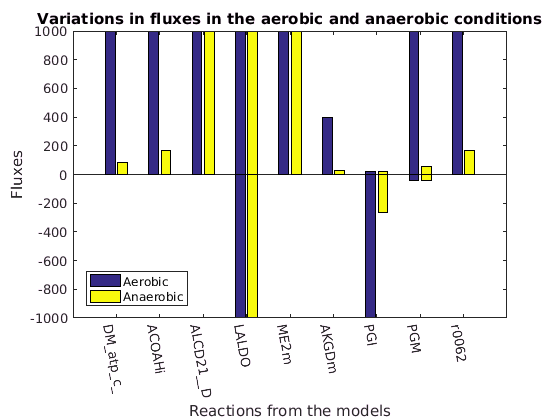

maxfxs = table2cell(maxf);
minfxs = table2cell(minf);

figure
plot1 = bar(cell2mat(maxfxs(1:end, :)));
hold on
plot2 = bar(cell2mat(minfxs(1:end, :)));
hold off
xticklabels({'DM_atp_c_', 'ACOAHi', 'ALCD21__D', 'LALDO',...
             'ME2m', 'AKGDm', 'PGI', 'PGM', 'r0062'})
set(gca, 'XTickLabelRotation', -80);
yticks([-1000 -800 -600 -400 -200 0 200 400 600 800 1000])
xlabel('Reactions from the models')
ylabel('Fluxes')
legend({'Aerobic', 'Anaerobic'}, 'Location', 'southwest')
title('Variations in fluxes in the aerobic and anaerobic conditions')

## 2) Fast FVA

When the number of reaction on which you want to perform a flux variability is higher to 1000, we recommend using `fastFVA()` function instead of `fluxVariability(). `Note that for large models the memory requirements may become prohibitive.

The `fastFVA()` function only supports the [CPLEX](https://opencobra.github.io/cobratoolbox/docs/solvers.html ) solver.

changeCobraSolver ('ibm_cplex', 'all', 1);


 > IBM ILOG CPLEX interface added to MATLAB path.
 > Solver for LP problems has been set to ibm_cplex.

 > IBM ILOG CPLEX interface added to MATLAB path.
 > Solver for MILP problems has been set to ibm_cplex.

 > IBM ILOG CPLEX interface added to MATLAB path.
 > Solver for QP problems has been set to ibm_cplex.
 > Solver ibm_cplex not supported for problems of type MIQP. Currently used: gurobi 
 > Solver ibm_cplex not supported for problems of type NLP. Currently used: matlab 


Run fastFVA analysis for the whole model (i.e. flux varaibility analysis performed on all reactions included in the model) with the constraints that simulates aerobic conditions:

[minFluxF1, maxFluxF1, optsol, ret, fbasol, fvamin, fvamax, statussolmin, statussolmax] = fastFVA(modelfva1);

 > The CPLEX version has been determined as 1271.
 >> Solving Model.S. (uncoupled) 
 >> The number of arguments is: input: 1, output 9.
 >> Size of stoichiometric matrix: (5063,7440)
 >> All reactions are solved (7440 reactions - 100%).
 >> 0 reactions out of 7440 are minimized (0.00%).
 >> 0 reactions out of 7440 are maximized (0.00%).
 >> 7440 reactions out of 7440 are minimized and maximized (100.00%).

 -- Starting to loop through the 4 workers. -- 

 -- The splitting strategy is 0. -- 

----------------------------------------------------------------------------------
--  Task Launched // TaskID: 1 / 4 (LoopID = 4) <> [5581, 7440] / [5063, 7440].
 >> The number of reactions retrieved is 1860
 >> Log files will be stored at /home/vanja/fork-cobratoolbox/src/analysis/FVA/fastFVA/logFiles
 -- Start time:     Tue Jul 25 16:13:21 2017
 >> #Task.ID = 1; logfile: cplexint_logfile_1.log

 -- Warning:: The optPercentage is higher than 90. The solution process might take longer than you exp

Run fast FVA analysis for the whole model with the constraints that simulates anaerobic conditions:

[minFluxF2, maxFluxF2, optsol2, ret2, fbasol2, fvamin2, fvamax2,...
    statussolmin2, statussolmax2] = fastFVA(modelfva2);

 > The CPLEX version has been determined as 1271.
 >> Solving Model.S. (uncoupled) 
 >> The number of arguments is: input: 1, output 9.
 >> Size of stoichiometric matrix: (5063,7440)
 >> All reactions are solved (7440 reactions - 100%).
 >> 0 reactions out of 7440 are minimized (0.00%).
 >> 0 reactions out of 7440 are maximized (0.00%).
 >> 7440 reactions out of 7440 are minimized and maximized (100.00%).

 -- Starting to loop through the 4 workers. -- 

 -- The splitting strategy is 0. -- 

----------------------------------------------------------------------------------
--  Task Launched // TaskID: 1 / 4 (LoopID = 4) <> [5581, 7440] / [5063, 7440].
 >> The number of reactions retrieved is 1860
 >> Log files will be stored at /home/vanja/fork-cobratoolbox/src/analysis/FVA/fastFVA/logFiles
 -- Start time:     Tue Jul 25 16:19:57 2017
 >> #Task.ID = 1; logfile: cplexint_logfile_1.log

 -- Warning:: The optPercentage is higher than 90. The solution process might take longer than you exp

Plot the results of the fast FVA and compare them between the aerobic and anaerobic models:

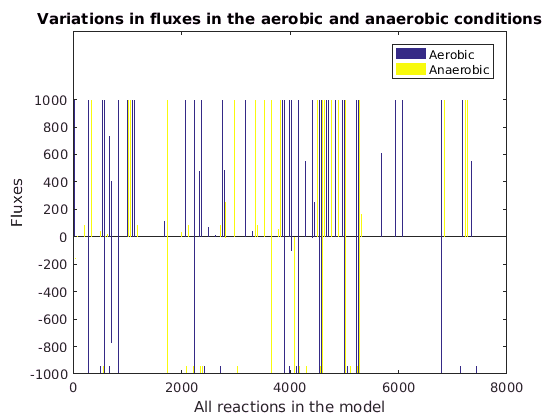

ymaxf1 = maxFluxF1;
yminf1 = minFluxF1;
ymaxf2 = maxFluxF2;
yminf2 = minFluxF2;

maxf =table(ymaxf1, ymaxf2);
minf =table(yminf1, yminf2);

maxf = table2cell(maxf);
minf = table2cell(minf);

figure
plot3 = bar(cell2mat(maxf(1:end, :)));
hold on
plot4 = bar(cell2mat(minf(1:end, :)));
hold off
xticks([0 2000 4000 6000 8000 10600])
yticks([-1000 -800 -600 -400 -200 0 200 400 600 800 1000])
xlabel('All reactions in the model')
ylabel('Fluxes')
legend({'Aerobic', 'Anaerobic'})
title('Variations in fluxes in the aerobic and anaerobic conditions')

## REFERENCES 

[1] Gudmundsson, S., Thiele, I. Computationally efficient flux variability analysis. *BMC Bioinformatics. *11, 489 (2010).

[2] Heirendt, L., Thiele, I., Fleming, R.M. DistributedFBA.jl: high-level, high-performance flux balance analysis in Julia. *Bioinformatics.* 33 (9), 1421-1423 (2017).

[3] Thiele, I., et al. A community-driven global reconstruction of human metabolism. *Nat. Biotechnol., *31(5), 419–425 (2013).